clc
clear

image_inputpath=fullfile("002-5/")

image_inputpath = "002-5\"

imds=imageDatastore(image_inputpath,"IncludeSubfolders",true, ...
    "LabelSource","foldernames")

imds =   ImageDatastore - 属性:

                       Files: {
                              'G:\2023.4Zr_data_processing\002-5\Rover and Rut\dh_img00004-3-3.png';
                              'G:\2023.4Zr_data_processing\002-5\Rover and Rut\dh_img00004-3-4.png';
                              'G:\2023.4Zr_data_processing\002-5\Rover and Rut\dh_img00004-4-1.png'
                               ... and 1355 more
                              }
                     Folders: {
                              'G:\2023.4Zr_data_processing\002-5'
                              }
                      Labels: [Rover and Rut; Rover and Rut; Rover and Rut ... and 1355 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


numclass=numel(categories(imds.Labels))

numclass = 7

meanAcc = 0.9801

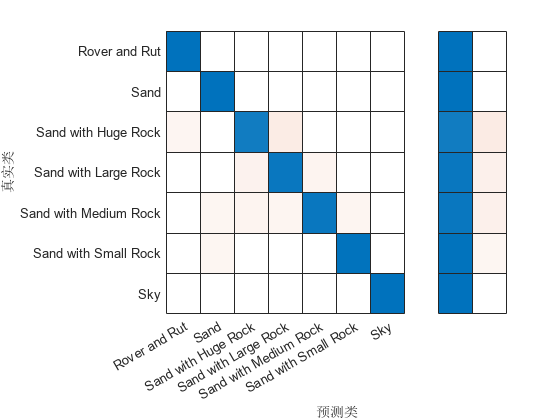

do_prediction=1;
if do_prediction
    Resnet50_inputsize=[224 224 3];
    augimds=augmentedImageDatastore(Resnet50_inputsize(1:2),imds);
    load Result001_2\002_resnet50_2023-12-08-16-07.mat
    [YPred,scores] = classify(net,augimds);
    meanAcc=nnz(YPred==imds.Labels)/numel(imds.Labels)
    close all
    figure(1)
    confusionchart(imds.Labels,YPred,"Normalization","row-normalized", ...
        "RowSummary","row-normalized");
    saveas(gcf,"Result001_2\002_all_confusionchart.png");
%     [conf,names]=confusionmat(imds.Labels,YPred);
%     figure(2)
%     heatmap(names,names,conf);
%     saveas(gcf,"Result001_2\002_all_heatmap.png");
end

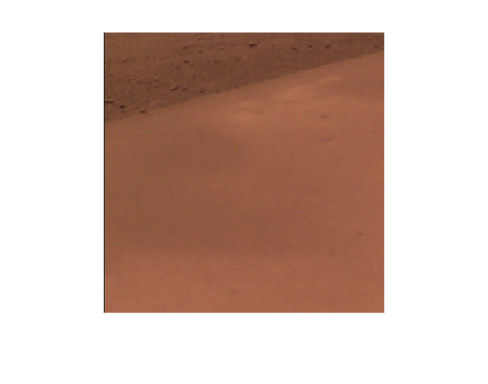

I_test=imread("002-1\dh_img00009-1-1.png");
I_test=imresize(I_test,[224 224]);
imshow(I_test)

[I_Pred,I_scores] = classify(net,I_test)

I_Pred = categorical
     Sand 


I_scores = 1×7 single 行向量
    0.0003    0.9990    0.0002    0.0001    0.0003    0.0001    0.0001
